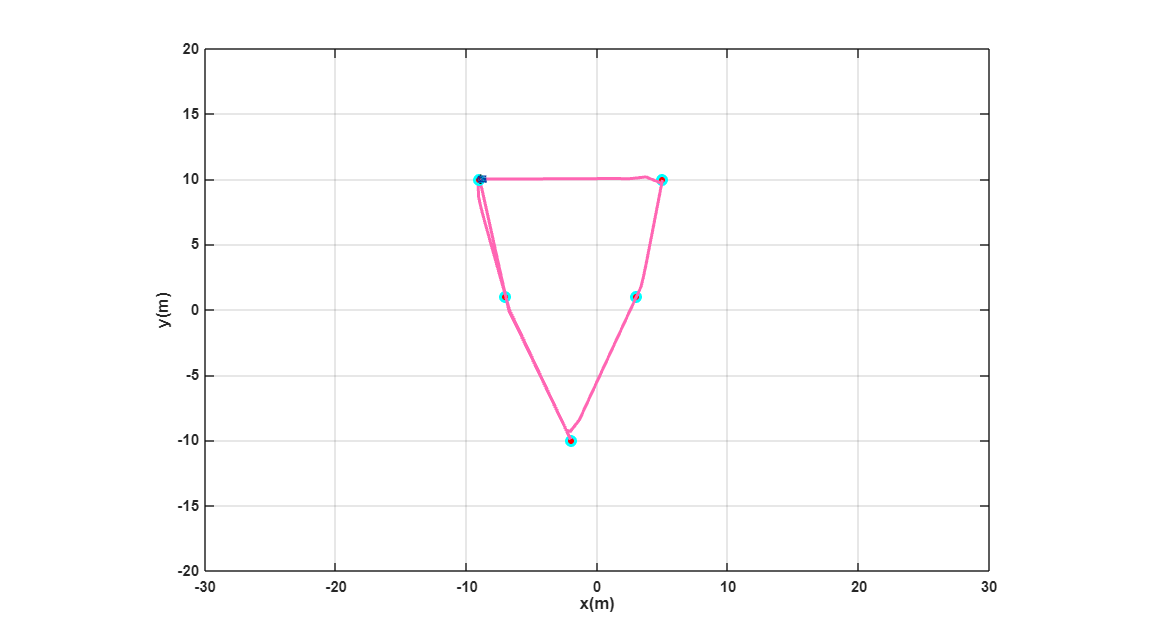

x1(1) = -9; 
y1(1) = 10;
phi(1) = pi/2;
hx(1) = x1(1);
hy(1) = y1(1);

coord = [  -7,  1;   
           -2, -10;   
            3,  1;   
            5,  10;
           -9, 10
                ];
ts = 0.1;
tf = 15;
N = tf / ts;
t = linspace(0, ts, N);

scale = 4;
sizeScreen = get(0,'ScreenSize');
scene = figure('Name','Animación trayectoria completa');
set(scene, 'Color','white', 'position', sizeScreen);
set(gca,'FontWeight','bold');
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([0 90]); % Orientación de la figura
axis([-30 30 -20 20 0 1]); % Límites de los ejes

% Mostrar los puntos deseados
hold on;
plot(coord(:,1), coord(:,2), 'ro', 'MarkerFaceColor', 'r'); % Puntos de destino

% Inicializar trazado
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2); % punto inicial


% Inicialización para cada segmento
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

for i = 1:size(coord,1)
    hxd = coord(i,1);
    hyd = coord(i,2);

    for k = 1:N
        
        hxe = hxd - hx(end);
        hye = hyd - hy(end);
        he = [hxe; hye];
        Error(k) = norm(he);
        
        J = [cos(phi(end)) -sin(phi(end)); sin(phi(end)) cos(phi(end))];

        Kp_base = 0.1;
        Kp_max = 1;
        Error_max = 2.0;
        error_norm = norm(he);
        Kp_k = Kp_base + (Kp_max - Kp_base) * tanh(error_norm/Error_max);
        K = Kp_k * eye(2);
        
        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);
        
        % Actualizar estado
        phi(end+1) = phi(end) + w(k)*ts;
        xp1 = v(k)*cos(phi(end-1));
        yp1 = v(k)*sin(phi(end-1));
        x1(end+1) = x1(end) + xp1*ts;
        y1(end+1) = y1(end) + yp1*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    % Actualizar animación del movimiento
    step = 5;  
    for k = length(hx)-N+1:step:length(hx)
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % punto objetivo
        pause(ts);
    end
end